# Ejercicio 2

Leemos la imagen y transformamos a grises. La imagen que utilizaremos es de 640x480 píxeles de tamaño.

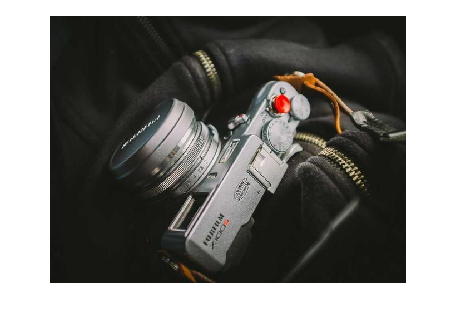

clearvars; close all;
image = imread('image2.jpg');
figure(); imshow(image);

grayimage = rgb2gray(image); % Numbers in uint8 between 0 and 255
image = double(grayimage); % Numbers in double between 0 and 255

Dividimos la imagen en sub-imágenes (o ventanas) del mismo tamaño. Escogemos un tamaño para que sea divisor de la resolución de la imagen con n.

[r,c] = size(image);
n = 16;
rsizes = n*ones(1,r/n);
csizes = n*ones(1,c/n);
windows = mat2cell(image, rsizes, csizes);

De este modo, tenemos `r/n * c/n` ventanas de `n` filas y `n` columnas, es decir, de n*n píxeles. De este modo, si definimos el tamaño de las ventanas en 16 píxeles, tendremos `640/16 * 480/16 = 40 * 30 = 1200 ventanas (N) `de `256 píxeles` cada una.

Formamos los patrones a partir de cada una de las sub-imágenes. Transformamos las ventanas en vectores fila de n*n elementos y lo guardamos en `patterns`.

counter = 1;
for i=1:r/n
    for j=1:c/n
        patterns(counter, :) = reshape(windows{i,j}, [1 n*n]);
        counter = counter + 1;
    end
end

En este punto, la variable `patterns` tiene N filas y n*n columnas. Cada fila representa una ventana colocada en forma de vector.

Ahora hay que generar la red neuronal competitiva. Definimos el número de neuronas (K) y las épocas y la entrenamos con los patrones en forma de columnas.

K = 100; % Same neurons as clusters
red = competlayer(K);
% Definition of the number of epochs
red.trainParam.epochs=100;
% Training
red = train(red, patterns');
% Weights matrix
W = red.IW{1}; % W is [n_clusters x 2]

Ahora debemos seleccionar para cada ventana, la ventana más representativa de las K ventanas obtenidas al entrenar la red neuronal. Para ello utilizamos `sim(red, aux)` donde `aux` es la ventana transformada en vector columna.

for i=1:r/n
    for j=1:c/n
        aux = reshape(windows{i,j}, [n*n 1]);
        sel = sim(red, aux);
        sel_index = find(sel);
        new_windows{i,j} = reshape(W(sel_index, :), n, n);
    end
end

Obtenemos la imagen a partir de las ventanas seleccionadas y comparamos resultados.

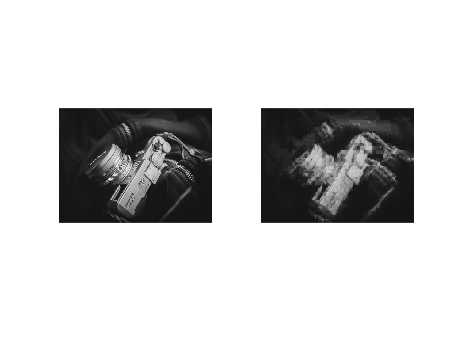

new_image = cell2mat(new_windows);
new_image = uint8(new_image);
figure(); 
subplot(1,2,1); imshow(grayimage);
subplot(1,2,2); imshow(new_image);